Trimming High Fidelity Model:
Trim Values and Cost:
cost   = 6.8917e-06
thrust = 2110.3284 lb
elev   = -2.0278 deg
ail    = -0.08632 deg
rud    = 0.068354 deg
alpha  = 3.6611 deg
dLEF   = 5.1352 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 6.8917e-06
thrust = 2110.3284 lb
elev   = -2.0278 deg
ail    = -0.08632 deg
rud    = 0.068354 deg
alpha  = 3.6611 deg
dLEF   = 5.1352 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 6.8917e-06
thrust = 2110.3284 lb
elev   = -2.0278 deg
ail    = -0.08632 deg
rud    = 0.068354 deg
alpha  = 3.6611 deg
dLEF   = 5.1352 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 6.8917e-06
thrust = 2110.3284 lb
elev   = -2.0278 deg
ail    = -0.08632 deg
rud    = 0.068354 deg
alpha  = 3.6611 deg
dLEF   = 5.1352 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 6.8917e-06
thrust = 2110.3284 lb
elev   = -2.0278 deg
ail    = -0.08632 deg
rud    = 0.068354 deg
alpha  = 3.6611 deg
dLEF   = 5.1352 deg
Vel.   = 500ft/s
Trim Values and Cost:
cost   = 6.8917e-0

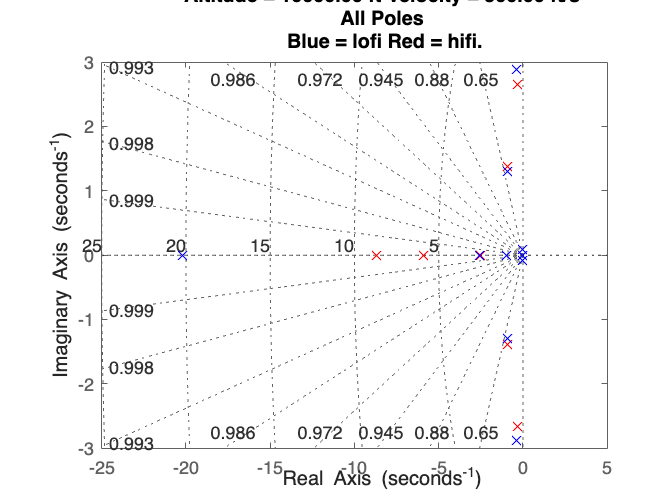

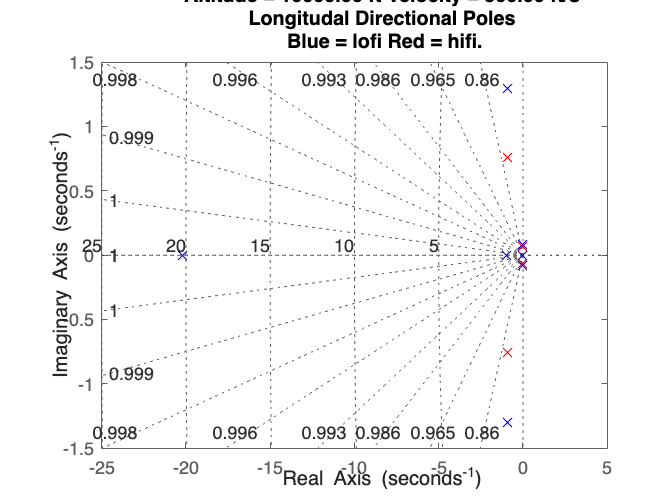

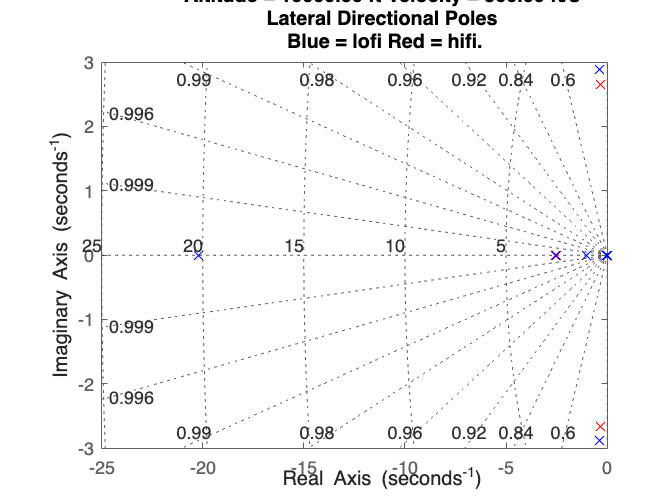

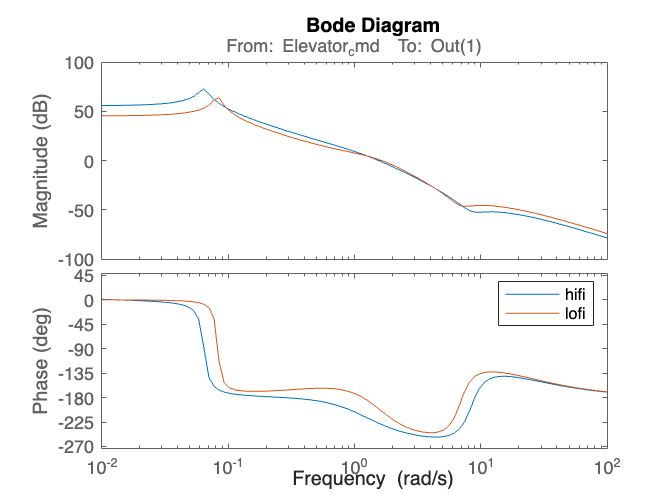

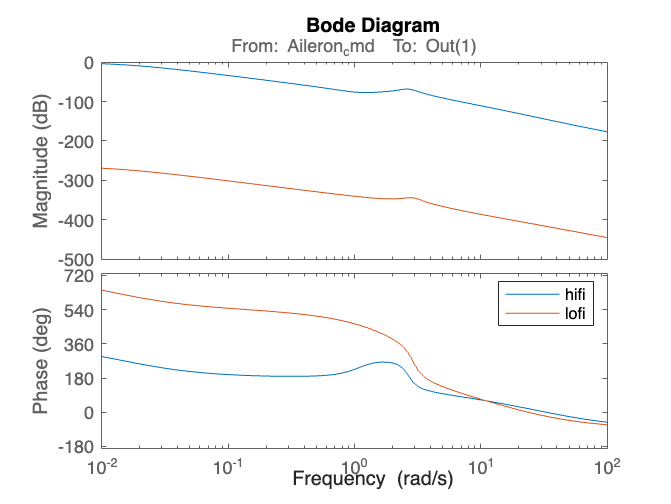

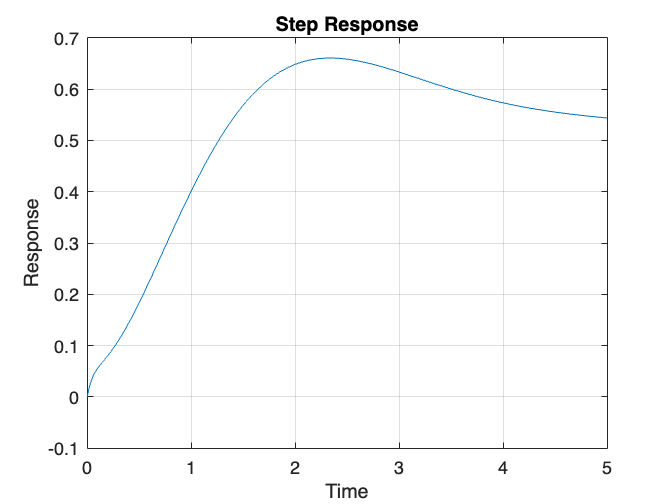

run("FindF16Dynamics.m")

lat_inputs_idx = [3, 4]; 
lat_states_idx = [4 6 10 12 9];
lat_outputs_idx = lat_states_idx;


%Low-Fidelity Model                 
reduced_model_states = [4 6 10 12 9];
reduced_model_inputs = [15 16]; 

A_8 = SS_lo.A(reduced_model_states, reduced_model_states);
B_8 = SS_lo.A(reduced_model_states,reduced_model_inputs);
C_8 = SS_lo.C(lat_outputs_idx, lat_states_idx);
D_8 = SS_lo.D(lat_outputs_idx, lat_inputs_idx);